colobj = roomspec();

resolution = 100;
binary_map = colobj2binary_map(colobj, resolution);

show(binary_map);
view(-90,90);

lidar = rangeSensor;

pose = [1 1 deg2rad(45)];
for i = 1:10 % Get time multiple times
    tic
    [ranges,angles] = lidar(pose,binary_map);
    toc
end

Elapsed time is 0.031941 seconds.
Elapsed time is 0.029652 seconds.
Elapsed time is 0.030000 seconds.
Elapsed time is 0.029054 seconds.
Elapsed time is 0.030020 seconds.
Elapsed time is 0.028812 seconds.
Elapsed time is 0.028588 seconds.
Elapsed time is 0.028774 seconds.
Elapsed time is 0.038502 seconds.
Elapsed time is 0.038298 seconds.


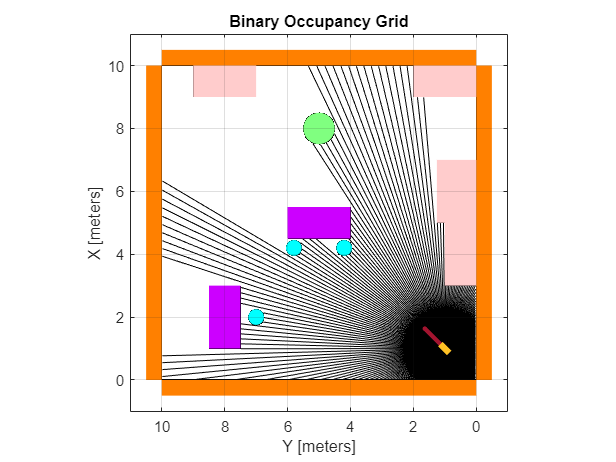


plot_scans(ranges, angles, pose);

robot=robotspec([0.4 0.2 0.2]);
hold on
robotshow(robot,pose);
roomshow(roomspec)
hold off

function plot_scans(ranges, angles, pose)
hold on

for i = 1:length(ranges)
    plot(pose(1)+[0 cos(pose(3)+angles(i))*ranges(i)], pose(2)+[0 sin(pose(3)+angles(i))*ranges(i)], 'k')
    
end

hold off
end